location = 'phobos.jpg';

x = imread(location);
r = size(x,1)

r = 1000

c = size(x,2)

c = 683

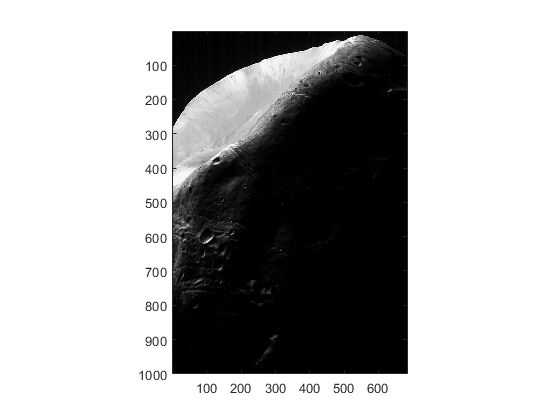

image(x);
colormap(gray(265));
axis image

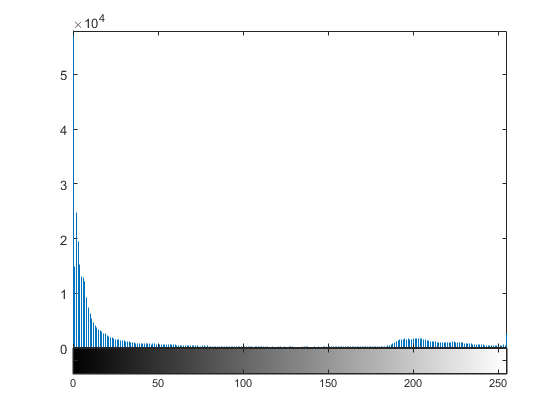

imhist(x);

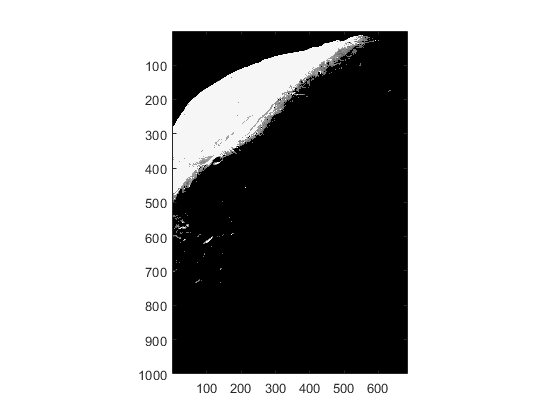


for i=1:r
    for k=1:c
        if (x(i,k) <100)
            x(i,k)= 0;
        end   
        if(x(i,k)>175)
            x(i,k)=255;
        end
    end
end

image(x);
colormap(gray(265));
axis image

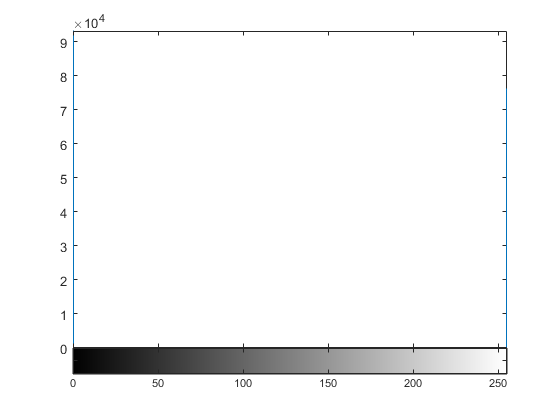

f=figure;
imhist(x);
saveas(f, 'phobosGray1Hist.png')

imwrite(x, gray(256), 'phobosGray1.jpg','jpg');


x = imread(location);
image(x);
colormap(gray(265));
axis image

imhist(x);

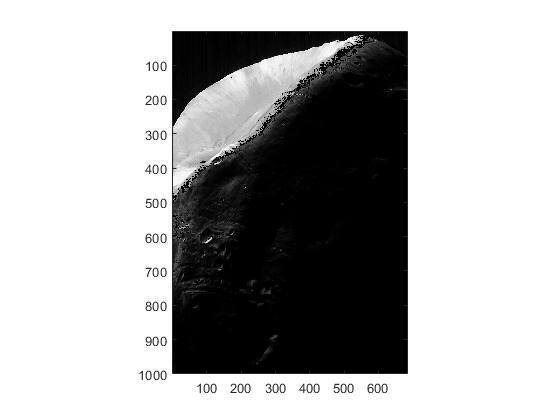


for i=1:r
    for k=1:c
        if (x(i,k) >= 100 ) && (x(i,k) <150)
            x(i,k)= 0;
        end   
    end
end

image(x);
colormap(gray(265));
axis image

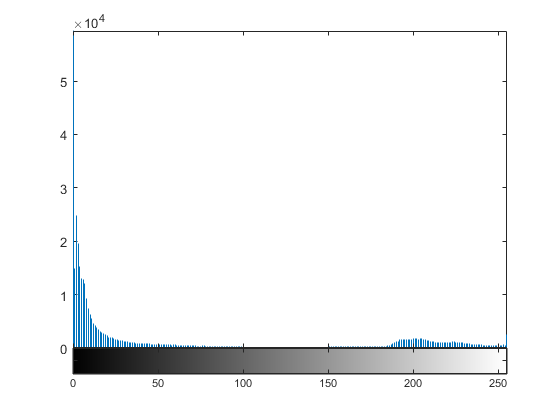

f=figure;
imhist(x);
saveas(f, 'phobosGray2Hist.png')

imwrite(x, gray(256), 'phobosGray2.jpg','jpg');

x = imread(location);
image(x);
colormap(gray(265));
axis image

imhist(x);

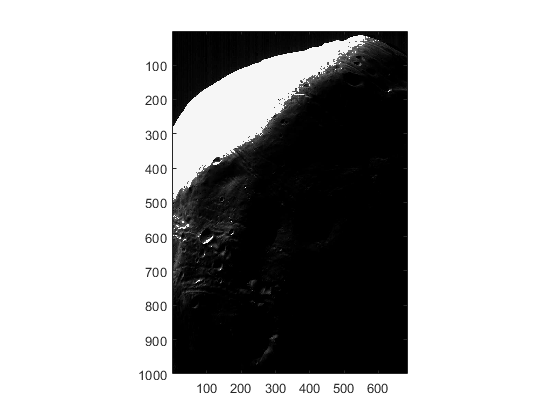


for i=1:r
    for k=1:c
        if (x(i,k) >120 )
            x(i,k)= 255;
        end   
    end
end

image(x);
colormap(gray(265));
axis image

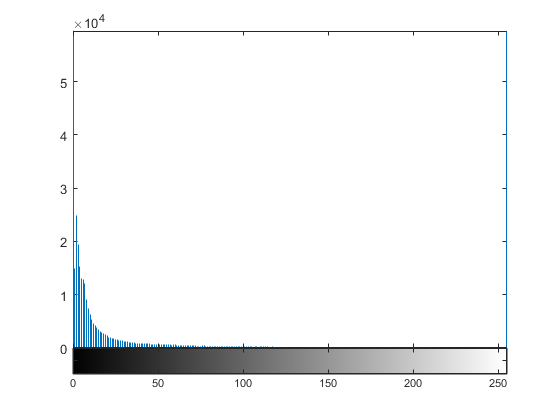

f=figure;
imhist(x);
saveas(f, 'phobosGray3Hist.png')

imwrite(x, gray(256), 'phobosGray3.jpg','jpg');

%{
x = imread(location);
image(x);
colormap(gray(265));
axis image
imhist(x);

for i=1:500
    for k=1:500
        if (x(i,k) <100)
            x(i,k)= 255;
        end   
    end
end

image(x);
colormap(gray(265));
axis image
f=figure;
imhist(x);
saveas(f, 'pollenGray1Hist.png')
imwrite(x, gray(256), 'pollenGray1.jpg','jpg');


x = imread(location);
image(x);
colormap(gray(265));
axis image
imhist(x);

for i=1:500
    for k=1:500
        if (x(i,k) >= 100 ) && (x(i,k) <150)
            x(i,k)= 0;
        end   
    end
end

image(x);
colormap(gray(265));
axis image
f=figure;
imhist(x);
saveas(f, 'pollenGray2Hist.png')
imwrite(x, gray(256), 'pollenGray2.jpg','jpg');

x = imread(location);
image(x);
colormap(gray(265));
axis image
imhist(x);

for i=1:500
    for k=1:500
        if (x(i,k) >120 )
            x(i,k)= 255;
        end   
    end
end

image(x);
colormap(gray(265));
axis image
f=figure;
imhist(x);
saveas(f, 'pollenGray3Hist.png')
imwrite(x, gray(256), 'pollenGray3.jpg','jpg');
%}
